**Bestimmung der Schwerbeschleunigung** *g*

**1. AUFGABENSTELLUNG **

Es soll die Schwerbeschleunigung g aus den Messdaten eines Fadenpendels mit der Länge **l = 1,0 m** ermittelt werden. Die Daten umfassen die **Zeit t**, den **Winkel phi **und die **Winkelgeschwindigkeit omega**.

**2. PHYSIKALISCHER ANSATZ**

Die Auswertung basiert auf dem Energieerhaltungssatz. Die Gesamtenergie eines Pendels ist konstant und setzt sich aus kinetischer und potenzieller Energie zusammen. Die Formel lautet:

## 
$$E_{\text{ges}} = \frac{1}{2} m l^2 \dot{\phi}^2 + m g l (1 - \cos(\phi))$$


**3. METHODIK**

Zur präzisen Bestimmung von g wurde die Energiegleichung linearisiert, um eine lineare Regression durchzuführen. Dabei wurden folgende Zuweisungen für die Achsen gewählt:

## 
$$\dot{\phi}^2 = - (2g/l) * (1 - cos(phi)) + const$$


- Y-Achse: $\dot{\phi}^2$ (proportional zur kinetischen Energie)

- X-Achse: $(1 - \cos(\phi))$ (proportional zur potenziellen Energie bzw. der relativen Höhe)

Über die Steigung der resultierenden Regressionsgeraden lässt sich g direkt berechnen. Der Zusammenhang ist:

## 
$$Steigung = - (2g/l) $$


## 
$$
g = -Steigung * l / 2$$


**4. ERGEBNISSE**

- Das Bestimmtheitsmaß $R^2$ liegt nahezu bei 1,0. Dies belegt eine extrem hohe Konsistenz der Daten mit dem physikalischen Modell.

- Der berechnete Wert für die Schwerbeschleunigung beträgt g = 1,6201 $m/s^2$.

**5. INTERPRETATION**

Der ermittelte Wert von etwa 1,62 $m/s^2$ entspricht der Gravitation auf der Mondoberfläche. Die Analyse bestätigt, dass die Messdaten ein physikalisch korrektes Pendel unter Mondbedingungen beschreiben.

% Fadenpendel - Teil 4: Bestimmung von g aus Messdaten
% Aufgabe: Lineare Regression zur Bestimmung der Schwerbeschleunigung

clear; clc; close all;

% --- Messdaten ---
% Zeile 1 ist t=0, phi=0, omega=1.0 (Nulldurchgang)
% Spalten: t [s], phi [rad], omega [rad/s]
data = [
    0.0000, 0.0000, 1.0000; 
    0.2222, 0.2193, 0.9604;
    0.4444, 0.4213, 0.8466;
    0.6667, 0.5910, 0.6712;
    0.8889, 0.7163, 0.4513;
    1.1111, 0.7895, 0.2040;
    1.3333, 0.8061, -0.0549;
    1.5556, 0.7653, -0.3108;
    1.7778, 0.6694, -0.5485;
    2.0000, 0.5241, -0.7518
];

t = data(:, 1);
phi = data(:, 2);
omega = data(:, 3);
l = 1.0; % Pendellänge in m

% --- Linearisierung für Regression ---
% Gleichung: omega^2 = - (2g/l) * (1 - cos(phi)) + const
% y = omega^2
% x = 1 - cos(phi)

y_reg = omega.^2;
x_reg = 1 - cos(phi);

% --- Lineare Regression (polyfit) ---
% p(1) ist die Steigung, p(2) ist der y-Achsenabschnitt

p = polyfit(x_reg, y_reg, 1);

slope = p(1);
intercept = p(2);

% --- Bestimmung von g ---
% slope = -2*g / l  =>  g = -slope * l / 2
g_calculated = -slope * l / 2;

fprintf('Ergebnis der Analyse:\n');

Ergebnis der Analyse:


fprintf('---------------------\n');

---------------------


fprintf('y-Achsenabschnitt der Regressionsgeraden: %.4f\n', intercept);

y-Achsenabschnitt der Regressionsgeraden: 1.0000


fprintf('Steigung der Regressionsgeraden: %.4f\n', slope);

Steigung der Regressionsgeraden: -3.2402


fprintf('Ermittelte Schwerbeschleunigung g:  %.4f m/s^2\n', g_calculated);

Ermittelte Schwerbeschleunigung g:  1.6201 m/s^2


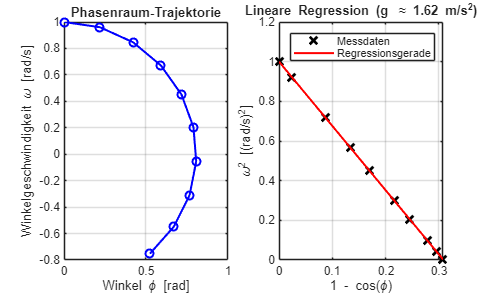


% --- Visualisierung ---
figure('Name', 'Bestimmung von g');

% Plot 1: Die Rohdaten 
subplot(1, 2, 1);
plot(phi, omega, 'bo-', 'LineWidth', 1.5);
xlabel('Winkel \phi [rad]');
ylabel('Winkelgeschwindigkeit \omega [rad/s]');
title('Phasenraum-Trajektorie');
grid on;

% Plot 2: Die Linearisierung
subplot(1, 2, 2);
plot(x_reg, y_reg, 'kx', 'MarkerSize', 8, 'LineWidth', 2); 
hold on;
x_fit = linspace(min(x_reg), max(x_reg), 100);
y_fit = polyval(p, x_fit);
plot(x_fit, y_fit, 'r-', 'LineWidth', 1.5);

xlabel('1 - cos(\phi)');
ylabel('\omega^2 [(rad/s)^2]');
title(['Lineare Regression (g \approx ' sprintf('%.2f', g_calculated) ' m/s^2)']);
legend('Messdaten', 'Regressionsgerade');
grid on;


% Zusatzcheck
% Wir pruefen, wie gut die Regression passt (Bestimmtheitsmass R^2)
y_resid = y_reg - polyval(p, x_reg);
SofS_resid = sum(y_resid.^2);
SofS_total = sum((y_reg - mean(y_reg)).^2);
R2 = 1 - SofS_resid/SofS_total;
fprintf('Bestimmtheitsmass R^2:           %.4f\n', R2);

Bestimmtheitsmass R^2:           1.0000
